# 1) Plot the following 2-D sequences in MATLAB:

clc
clear all
close all 
[n1 n2]=meshgrid(-5:5,-5:5);

## (i) Impulse.

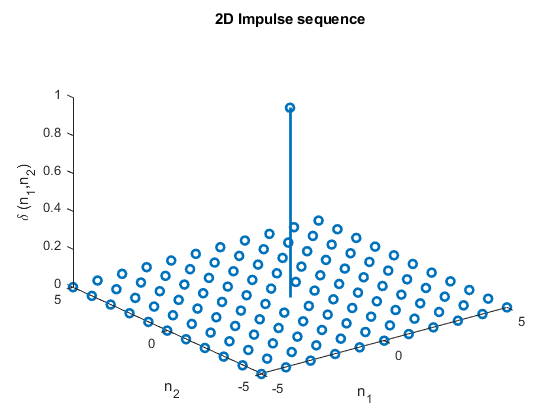

imp=[n1==0 & n2==0]; figure; stem3(n1,n2,imp,'linewidth',2); grid; % 2D Impulse
xlabel('n_1'); ylabel('n_2'); zlabel('\delta (n_1,n_2)'); title('2D Impulse sequence');

## (ii) horizontal and vertical impulses.

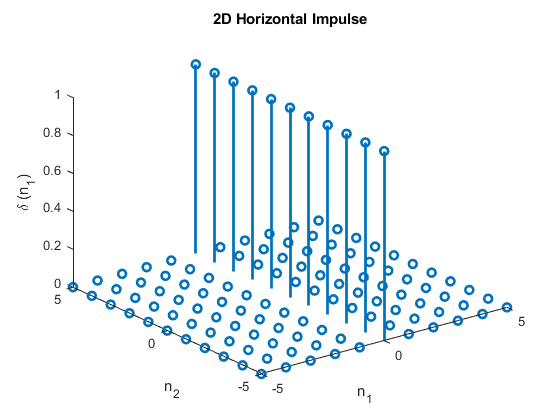

H_imp=[n1==0]; figure; stem3(n1,n2,H_imp,'linewidth',2); grid; % 2D Horizontal Impulse 
xlabel('n_1'); ylabel('n_2'); zlabel('\delta (n_1)'); title('2D Horizontal Impulse');

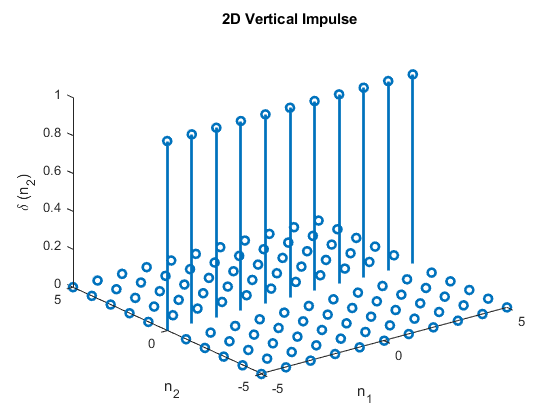

V_imp=[n2==0]; figure; stem3(n1,n2,V_imp,'linewidth',2); grid; % 2D Vertical Impulse
xlabel('n_1'); ylabel('n_2'); zlabel('\delta (n_2)'); title('2D Vertical Impulse');

## (iii) step sequence.

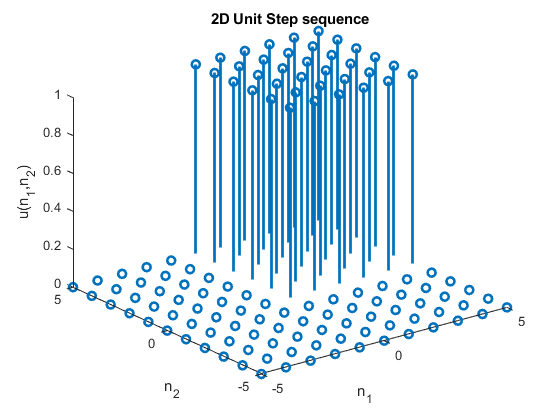

step=[n1>=0 & n2>=0]; figure; stem3(n1,n2,step,'linewidth',2); grid; % Step Sequence
xlabel('n_1'); ylabel('n_2'); zlabel('u(n_1,n_2)'); title('2D Unit Step sequence')

## (iv) exponential sequence.

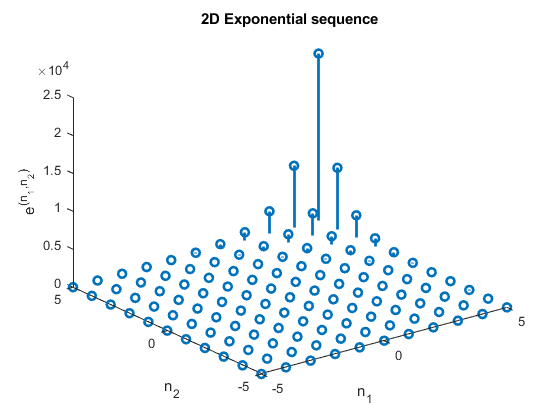

a=0.5; b=0.2;
Exp=(exp(n1)).*(exp(n2)); figure; stem3(n1,n2,Exp,'linewidth',2); grid; % 2D Exponential Seq.
xlabel('n_1'); ylabel('n_2'); zlabel('e^{(n_1,n_2)}'); title('2D Exponential sequence')

# 2) Write a MATLAB code for 1-D convolution and extend this for computing 2-D convolution of separable sequences. 

xn=[7 8 9; 4 5 6; 1 2 3];
h_n1_n2=[1 -3 1; -3 9 -3; 1 -3 1];
h_n1=[1 -3 1]';
h_n2=[1 -3 1];

for i=1:3
conv_col(:,i)= Conv1D(xn(:,i)',h_n1')'; % Function code is in the last 
end

for i=1:5
conv_row(i,:) = Conv1D(conv_col(i,:),h_n2);
end
convolved2D=conv_row;
disp("Convolved 2D output using 1D convolution Row and Column wise = ");

Convolved 2D output using 1D convolution Row and Column wise = 


disp(convolved2D);

     7   -13    -8   -19     9
   -17    32    19    44   -21
    -4     7     5    13    -6
     1    -4     1     8    -3
     1    -1    -2    -7     3



out=conv2(xn,h_n1_n2,'full');
disp("Convolved 2D output directly for verification = ");

Convolved 2D output directly for verification = 


disp(out);

     7   -13    -8   -19     9
   -17    32    19    44   -21
    -4     7     5    13    -6
     1    -4     1     8    -3
     1    -1    -2    -7     3



3) Write a MATLAB code to separate the 2-D impulse response into 1-D impulse responses.

hn1n2=[1 -3 1; -3 9 -3; 1 -3 1]; %input('Enter the Matrix to be seperate into row and column vector = ')
[r c]=size(hn1n2);
if (r~=c)
    disp('Matrix must be squre matrix')
elseif (det(hn1n2)~=0)
    disp('Matrix is not singular')
else
    disp('The Matrix is seperable')
end

The Matrix is seperable


cdr=gcd(sym(hn1n2(:,1)));
cdc=gcd(sym(hn1n2(1,:)));
hn1=(1/cdr)*(hn1n2(1,:));
hn2=(1/cdc)*(hn1n2(:,1));
display(hn1, "Row Vector")

$$\left(\begin{array}{ccc} 1 & -3 & 1 \end{array}\right)$$

display(hn2, "Column Vector")

$$\left(\begin{array}{c} 1\\ -3\\ 1 \end{array}\right)$$

# 4) Consider a digital image of size 512 × 512 and apply the amplitude quantization at 

## (i) 8 bits/pixel, 

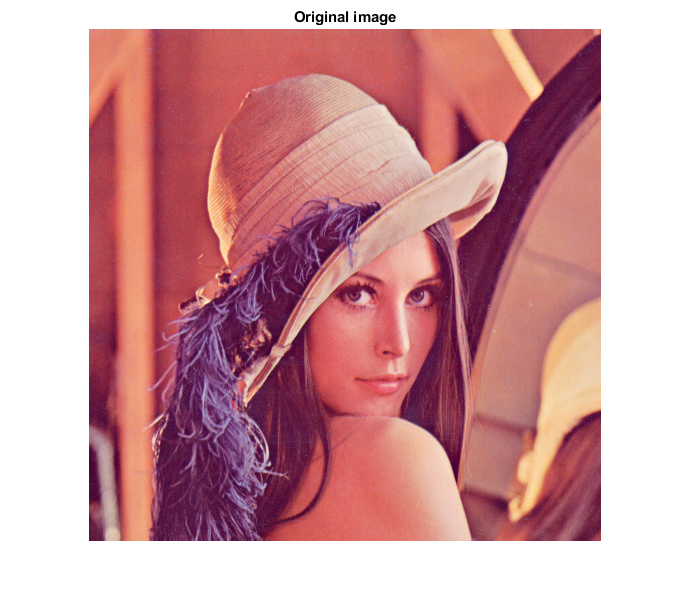

[I1 map]=imread("lenna.bmp");
figure; imshow(I1,map); title("Original image");

[r c ch] = size(I1);
if ch>=2;
    I1=rgb2gray(I1);
%     figure; imshow(I1); title("GreyScal image");
end

thresh=multithresh(I1,8); % Calculating Thresholds for 8 bits
seg_I=imquantize(I1,thresh); % Applying thresholds to obtain segmented image
RGB=label2rgb(seg_I); % Assigning the RGB color to the labels
figure; subplot(221); imshow(RGB); title("Segmented image 8bits/[pixel");

(ii) 6 bits/pixel.

thresh=multithresh(I1,6); % Calculating Thresholds for 6 bits
seg_I=imquantize(I1,thresh); % Applying the thresholds to obtain segmented image
RGB=label2rgb(seg_I); % Assigning the RGB color to the labels
subplot(222); imshow(RGB); title("Segmented image 6bits/[pixel");

(iii) 2 bits/ pixel.

thresh=multithresh(I1,2); % Calculating Thresholds for 2 bits
seg_I=imquantize(I1,thresh); % Applying the thresholds to obtain segmented image
RGB=label2rgb(seg_I); % Assigning the RGB color to the labels
subplot(223); imshow(RGB); title("Segmented image 2bits/[pixel");

(iv) 1 bit/pixel. 

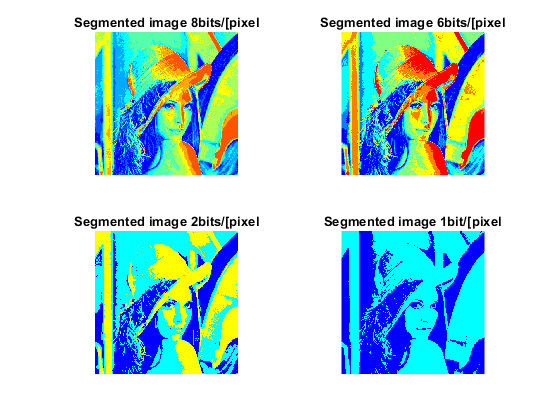

thresh=multithresh(I1,1); % Calculating Thresholds for 1 bits
seg_I=imquantize(I1,thresh); % Apply the thresholds to obtain segmented image
RGB=label2rgb(seg_I); % Assigning the RGB color to the labels
subplot(224); imshow(RGB); title("Segmented image 1bit/[pixel");

## Conclusion : Thare is a significant change in the color / intevsity image for diffrent number of bits/pixels

# 5) Consider a digital image of size 512 X 512 and reduce pixels to (i) 256 X 256, (ii) 128 X 128, (iii)

# 64 X 64, (iv) 32 X 32. Comment on the variation on the image.

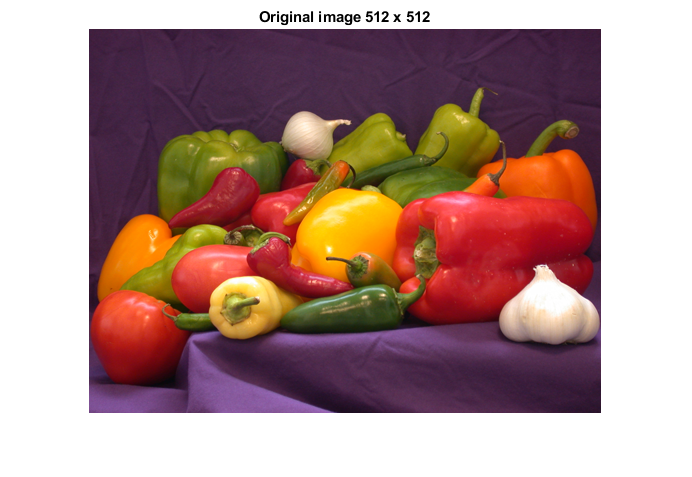

I=imread("peppers.png"); % Reading Image of size 512x512
figure; imshow(I); title("Original image 512 x 512");

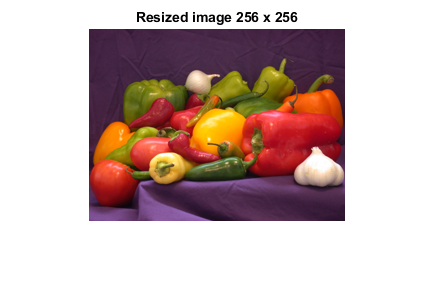

I_256=imresize(I,0.5); % Resizing Image for size 256x256.
figure; imshow(I_256); title("Resized image 256 x 256");

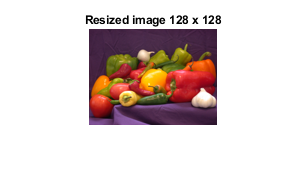

I_128=imresize(I,0.25); % Resizing Image for size 128x128
figure; imshow(I_128); title("Resized image 128 x 128");

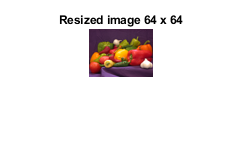

I_64=imresize(I,0.125); % Resizing Image for size 64x64
figure; imshow(I_64); title("Resized image 64 x 64");

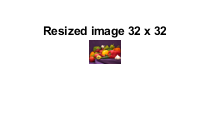

I_32=imresize(I,0.0625); % Resizing Image for size 32x32
figure; imshow(I_32); title("Resized image 32 x 32");

# 6) Use an image file of your choice and pass it through a low-pass filter whose impulse response is

# given in Fig. 1, and observe the output.

#                                                        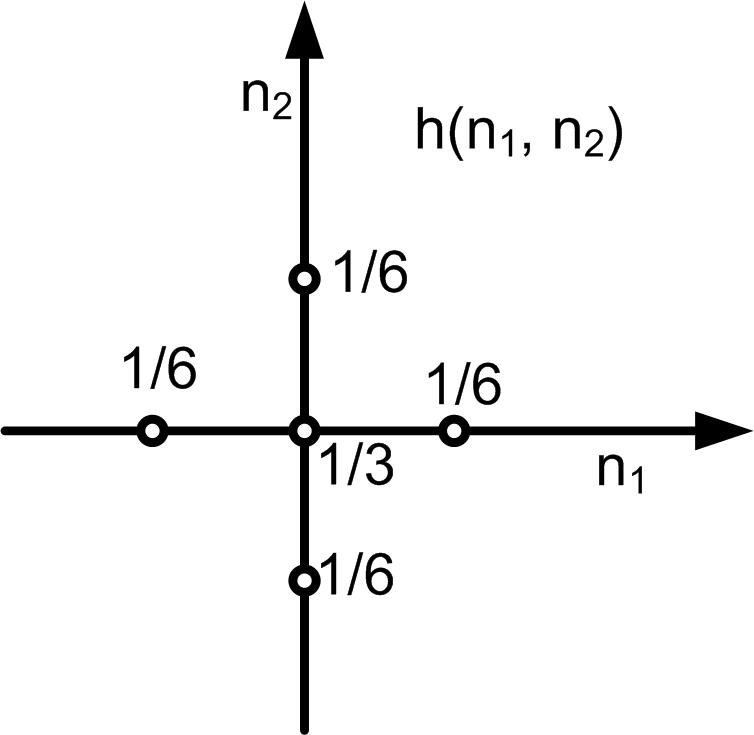

                                                                                                      Fig. 1. Low-pass filter impulse response

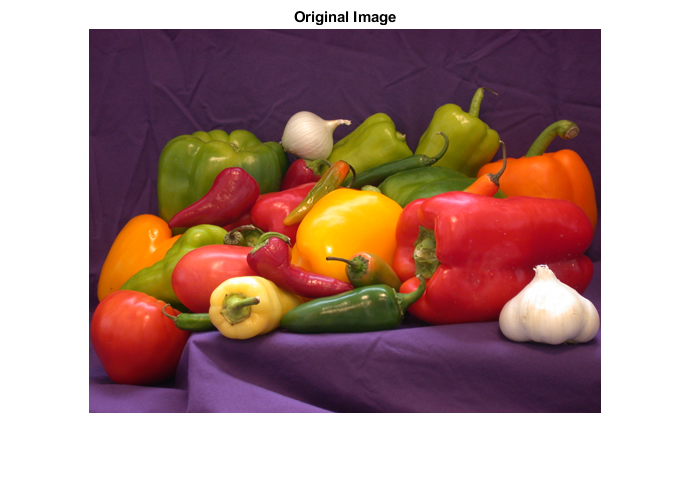

I_512 =  imread('peppers.png'); % Reading Image in RGB format  
LPF = [0 1/6 0;1/6 1/3 1/6;0 1/6 0]; % Creating LFP
Io = imfilter(I_512,LPF); % Passing image throgh LPF.

Ig = rgb2gray(I_512); % Converting from RGB to Gray scale image.
Iout = uint8(round(conv2(Ig, LPF, 'same')));  % Filtering Image throgh LPF
figure; imshow(I_512); title('Original Image'); % Plotting Origibal Image

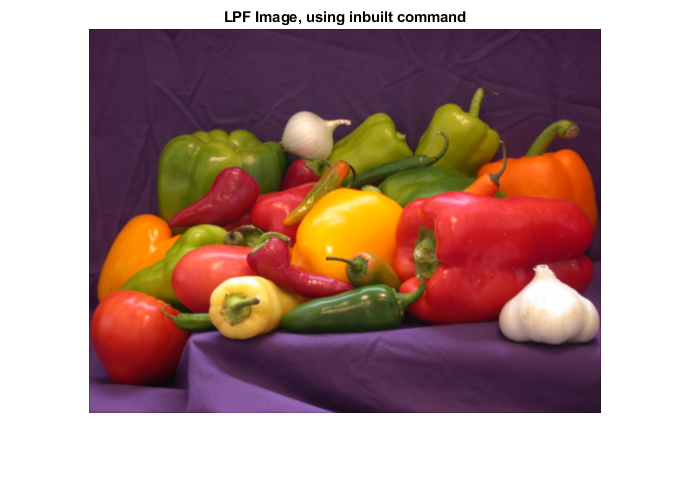

figure; imshow(Io); title('LPF Image, using inbuilt command'); % LPF'ed Image

## Conclusion : Filtered Image throgh LFP, got Blurred compare to Original Image

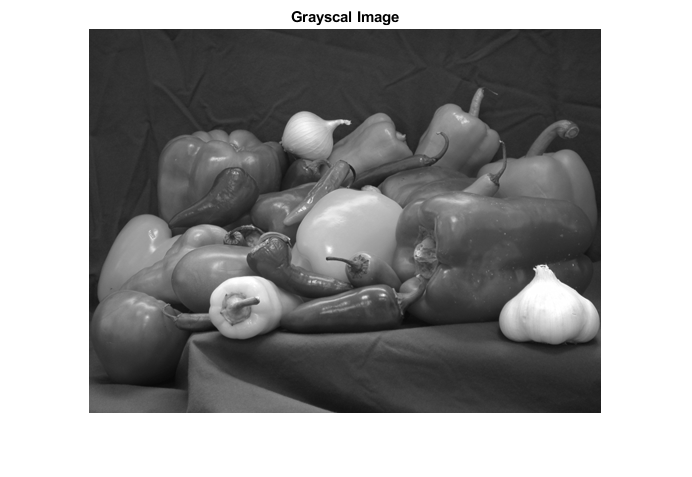

figure; imshow(Ig); title('Grayscal Image'); % Plotting Grayscal Image

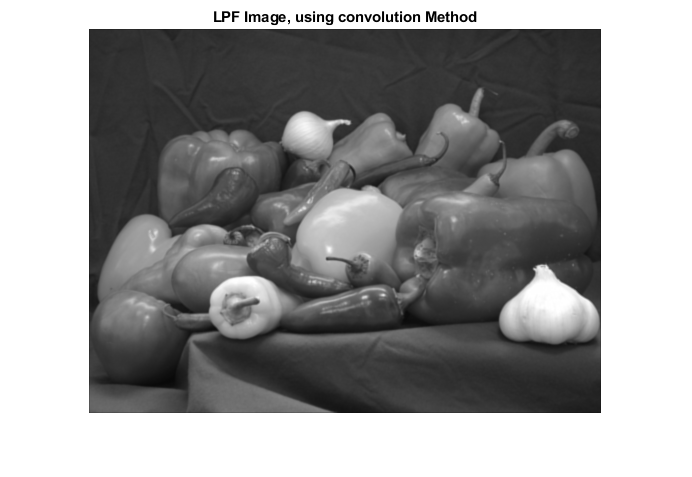

figure; imshow(Iout); title('LPF Image, using convolution Method'); % LPF Image using Convolution method

## Conclusion : Filtered Image throgh LFP, got Blurred compare to Original Image

# 7) Use an image file of your choice and pass it through a high-pass filter whose impulse response is

# given in Fig. 2, and comment on the output.

                                                                                                                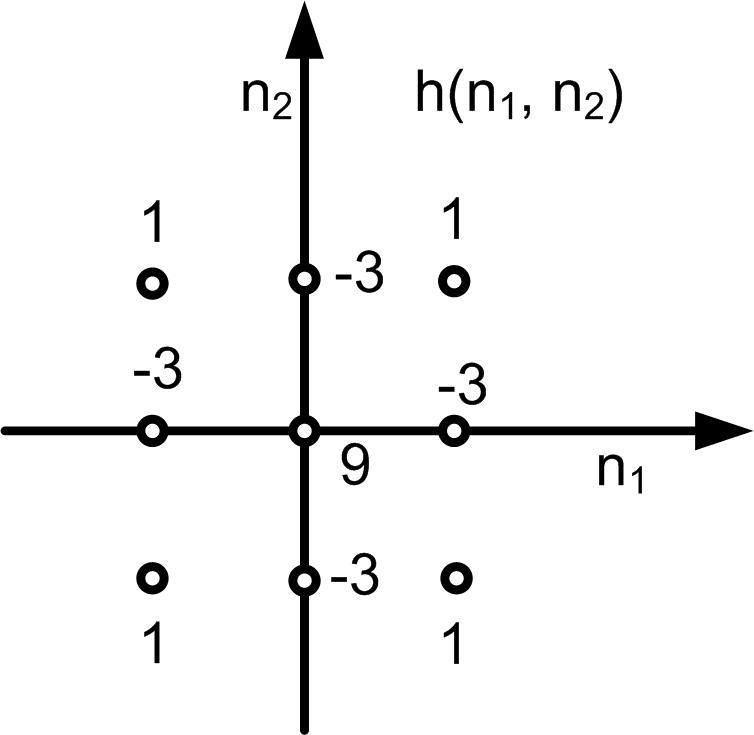

                                                                                                                   Fig. 2. High-pass filter impulse response

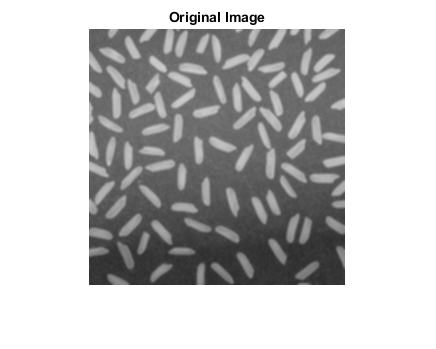

Ig =  imread('riceblurred.png'); % Reading Image in RGB format  
figure; imshow(Ig); title('Original Image'); % Plotting Origibal Image

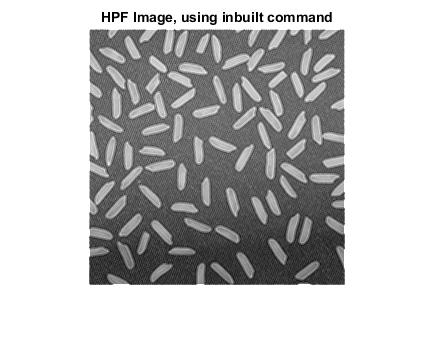

HPF=[1 -3 1;-3 9 -3;1 -3 1]; % Creating HPF
Io = imfilter(Ig,HPF); % Passing Image Throgh HPF
figure; imshow(Io); title('HPF Image, using inbuilt command') % HPF Image, using inbuilt command

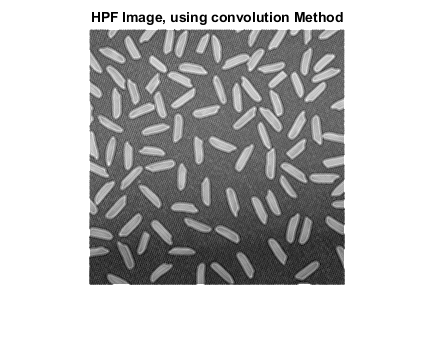

Iout = uint8(round(conv2(Ig, HPF, 'same'))); % Convolving Image with HPF
figure; imshow(Iout); title('HPF Image, using convolution Method') % HPF Image, using convolution Method

## Conclusion : Image got Sharpen after Paassing throgh HPF

# Function for 1D Convolution 

function yn = Conv1D(xn,hn)
m=length(xn);
n=length(hn);
X=[xn,zeros(1,n)];
H=[hn,zeros(1,m)]; 
for i=1:n+m-1
    yn(i)=0;
    for j=1:m;
        if(i-j+1>0)
            yn(i)=yn(i)+X(j)*H(i-j+1);
        else
        end
    end
end
end